% Scalar Standard Brownian Motion = Standard Wiener Process
Ns = 10; % Number of realizations
T = 10; % Final time
N = 1000; % Number of time steps
seed = 100; % Seed for reproducibility

% Realization of Ns Standard Brownian Motions
rng(seed);
dt = T/N;
dW = sqrt(dt)*randn(Ns,N);
W = cumsum(dW,2);
t=1:N;
plot(t,W)

%Scalar Standard Wiener Process
[W,Tw,dW] = ScalarStdWienerProcess(10,1000,10,100);
plot(Tw,W,'linewidth',2);

%Scalar Sample Mean and Sample Variance (Std Deviation)
[W,Tw,dW] = ScalarStdWienerProcess(T,N,Ns,seed);
[Wmean,sW,Wmeanp2sW,Wmeanm2sW]=ScalarSampleMeanStdVar(W)

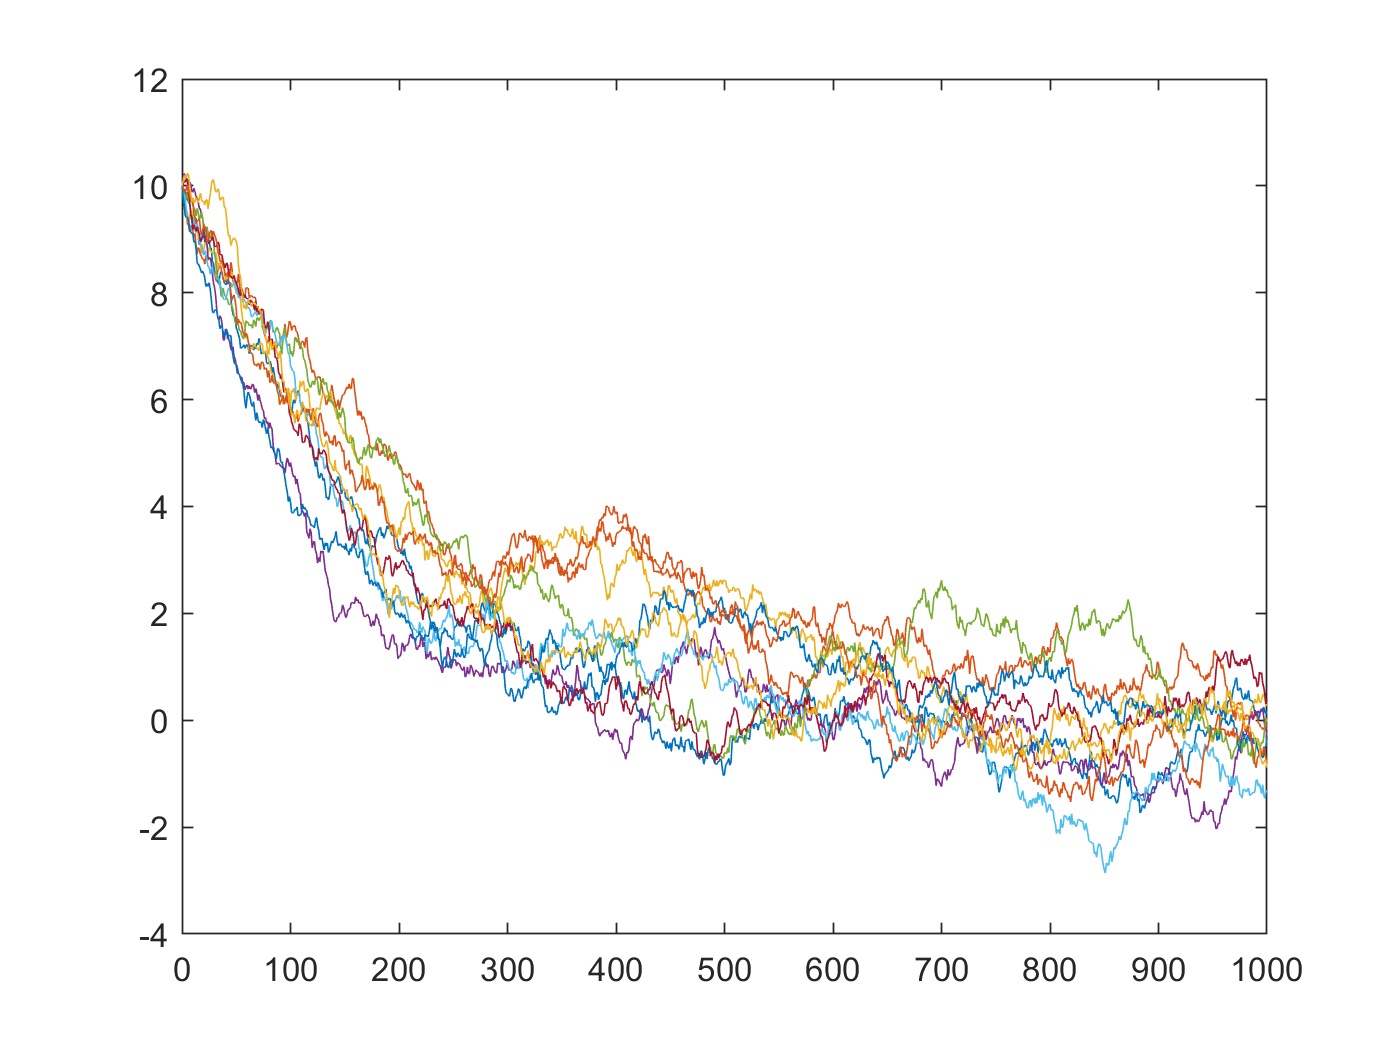

%Stochastic Differential Equation 
T = 10;
N = 1000;
Ns = 10;
seed = 100;
t=0:N;%for plot
x0 = 10;
lambda = -0.5;
sigma = 1.0;

[W,Tw,dW]=ScalarStdWienerProcess(T,N,Ns,seed);

X = zeros(size(W));
for i=1:Ns
X(i,1) = x0;
for k=1:N
dt = Tw(k+1)-Tw(k);
X(i,k+1) = X(i,k) + lambda*X(i,k)*dt + sigma*dW(i,k);
end
end
plot(t,X)

%Euler-Maruyama Method (explicit-explicit)
T = 10;
N = 1000;
Ns = 10;
seed = 100;
t=0:N;%for plot
x0 = 10;
lambda = -0.5;
sigma = 1.0;
p = [lambda; sigma];

[W,Tw,dW]=ScalarStdWienerProcess(T,N,Ns,seed);
X = zeros(size(W));
for i=1:Ns
X(i,:) = SDEeulerExplicitExplicit(@LangevinDrift,@LangevinDiffusion,Tw,x0,W(i,:),p);
end
plot(t,X)

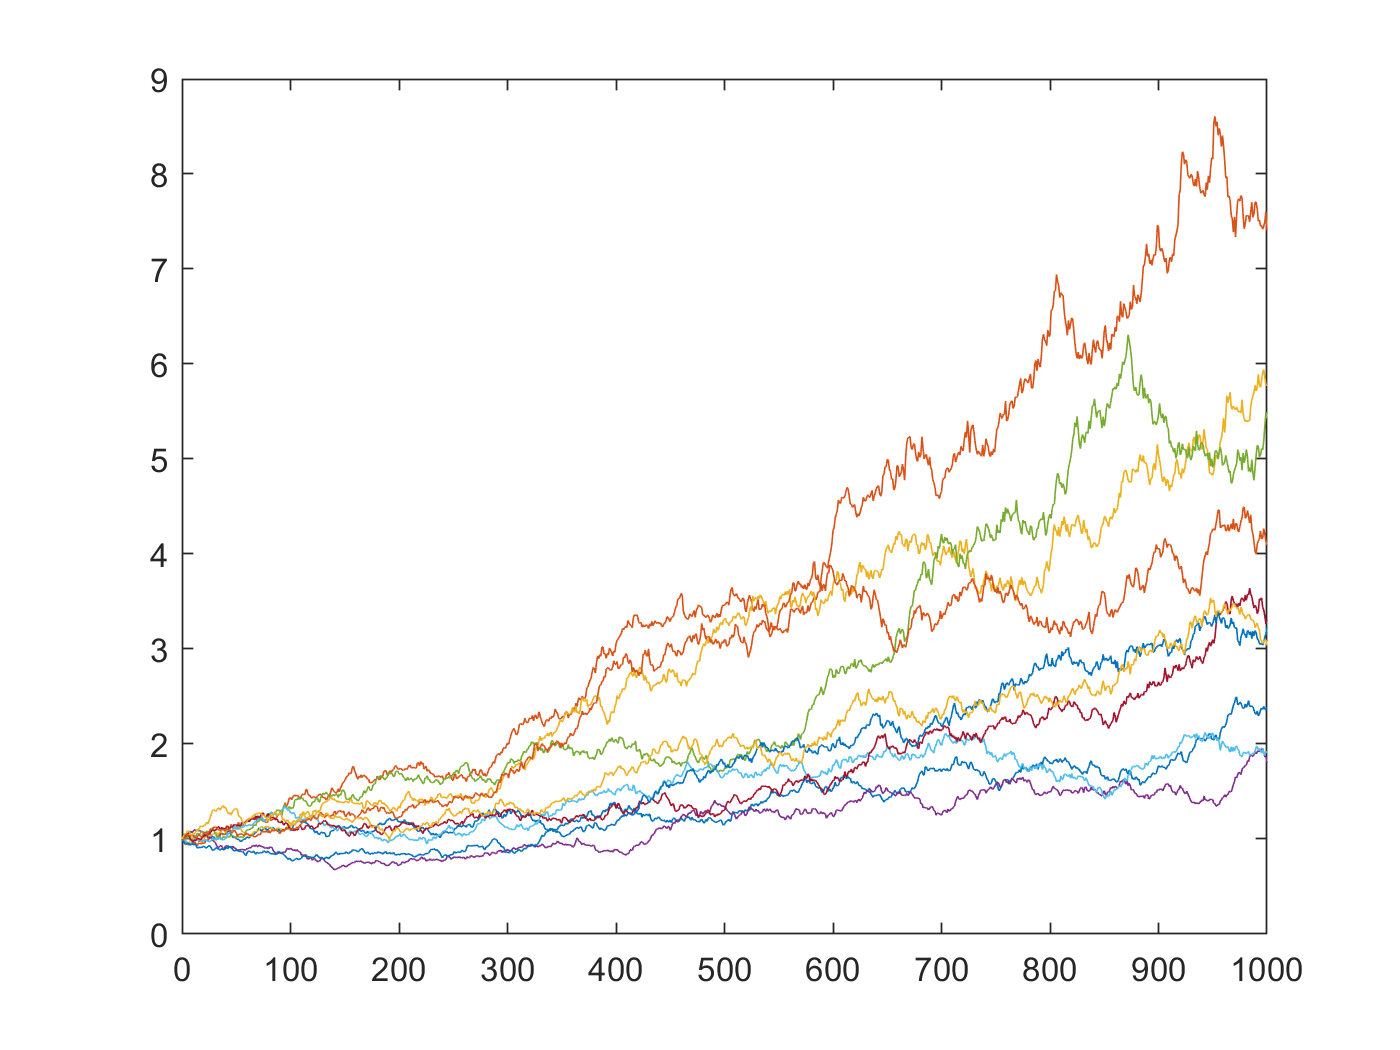

%Geometric Brownian Motion
T = 10;
N = 1000;
Ns = 10;
seed = 100;
t=0:N;%for plot
x0 = 1;
lambda = 0.15;
sigma = 0.15;
p = [lambda; sigma];

[W,Tw,dW]=ScalarStdWienerProcess(T,N,Ns,seed);
X = zeros(size(W));
for i=1:Ns
X(i,:) = SDEeulerExplicitExplicit(...
@GeometricBrownianDrift,@GeometricBrownianDiffusion,...
Tw,x0,W(i,:),p);
end
plot(t,X)

%newton method not tested

# *对于微分方程的欧拉方法，是前向差分，还是后向差分*

*Explicit methods* calculate the state of a system at a later time from the state of the system at the current time, while *implicit methods* find a solution by solving an equation involving both the current state of the system and the later one.